# GGV Map Creation

### 使い方

- vehicle_parameter_nit00.mlxでパラメータ設定

- simulation

### 注意事項

・vehicle dynamics block setを入れてください

・MFevalを入れてください

### シミュレーション条件設定

%最大ホイール端転舵角 [deg]
maxWhlAng = 25; %このモデルはパラレルステア

%最大ホイール端舵角に達するまでの時間(1/転舵周波数) [s]
SteerFrq = 30;

%転舵開始時間 [s]
steerstartTime = 10; % 10推奨

### コーナリングシミュレーション

% ------------------------------------------------------
% ここから下はGGVマップを作製するセクションです
% 修正を加える場合は中身を理解した上で行ってください
% ------------------------------------------------------

open_system('vehicle_cornering_aero_model'); % simを開く

dv = 5; % 速度のステップ量
v_max = (maxRev/gearRatio)*(pi/30)*((tireD/2)*0.0254)*3.6 % 最高速度(モーターの限界)

v_max = 103.7354

v = (10:dv:v_max)' ;
if v(end)~=v_max
    v = [v;v_max] ;
end

aymax = zeros(length(v),1);
phimax = zeros(length(v),1);

disp('vref=')

vref=


set_param('vehicle_cornering_aero_model', 'FastRestart', 'on'); % 高速再起動を有効化
for i = 1:length(v)
    vref = v(i,1);

    out = sim("vehicle_cornering_aero_model.slx");

    aymaxi = max(out.ay.Data);
    aymax(i,:) = aymaxi;

    phimaxi = max(out.phi.Data);
    phimax(i,:) = phimaxi;

    disp(vref)
end

    10

    15

    20

    25

    30

    35

    40

    45

    50

    55

    60

    65

    70

    75

    80

    85

    90

    95

   100

  103.7354



set_param('vehicle_cornering_aero_model', 'FastRestart', 'off'); % 高速再起動オフ

### 加減速シミュレーション

% MFeval
% パラメータの設定
SRmax = 0.7;
TS = 0;      %ターンスリップ[1/m]

% データ点数の定義
nPoints = 50; %必ず偶数

% Select a Use Mode
useMode = 111;

axmax_dec = zeros(length(v),1);
axmax_acc = zeros(length(v),1);

% friction ellipse points
N = 45 ;
% map preallocation
GGV = zeros(length(v),2*N-1,3) ;

for i = 1:length(v)
    vref = v(i,1);
    
    df = -0.5*rho*Af*Cl*(vref/3.6)^2; % ダウンフォース
    Fxd = 0.5*rho*Af*Cd*(vref/3.6)^2; % ドラッグ
    MtrSpd = (vref/3.6)*(30/pi)*gearRatio/(0.0254*tireD/2); % モーター回転数

    Trq = ptr_eff*maxPower*1000/(MtrSpd*2*pi/60); % 理論上のモータートルク

    if Trq <= maxTrq      % トルクカット(Yamaha Proto)
        Trqmax = Trq;
    else
        Trqmax = maxTrq;
    end
    Fx_Mtr = num_motors*Trqmax*gearRatio/(tireD*0.0254/2); % モーター駆動力

    % Pure longitual slip
    % Calculate inputs parameter
    Fz_dec = ones(nPoints/2,1).*(9.8*m/4 + df*Ab/2); % 減速時前輪1輪荷重
    Fz_acc = ones(nPoints/2,1).*(9.8*(m*(1-wd)/2 + df*(1-Ab)/4)); % 加速時後輪1荷重
    Fz = [Fz_dec; Fz_acc]; % 一つのFzにまとめ，simは加減速同時に行う
    kappa = linspace(-SRmax,SRmax,nPoints)'; % Slip ratio
    alpha = zeros(nPoints,1); % Slip angle
    gamma = ones(nPoints,1).*deg2rad(Gamma); % キャンバー角
    phit = ones(nPoints,1).*TS; % ターンスリップ
    Vx = ones(nPoints,1).*(vref/3.6); % 対地速度
    P = ones(nPoints,1).*Prs; % 内圧

    Frr_dec = Crr*(9.8*m + df); % 転がり抵抗
    Frr_acc = Crr*(9.8*m + df);

    %Wrap all inputs in one matrix
    inputs1 = [Fz kappa alpha gamma phit Vx P]; % MFeval入力

    % Store the output from mfeval in a 2D matrix
    output1 = mfeval(TIRfile,inputs1,useMode); % MFeval結果 警告出るけど大丈夫

    % Extract variables from outputs
    Fx_dec_maxi = min(output1(:,1)); % 1輪最大減速力
    Fx_acc_maxi = max(output1(:,1)); % 1輪最大加速力
    
    ax_dec_maxi = (2*Fx_dec_maxi - Fxd -Frr_dec)/(m*9.8); % 前2輪減速加速度
    axmax_dec(i,:) = ax_dec_maxi; % 格納

    axmax_acc_tire = (num_pw_wheel*Fx_acc_maxi - Fxd -Frr_acc)/(m*9.8); % タイヤが出せる後輪最大加速度
    axmax_acc_Mtr = (Fx_Mtr - Fxd -Frr_acc)/(m*9.8); % モーターが出せる後輪最大加速度
    axmax_acc(i,:) = min(axmax_acc_Mtr,axmax_acc_tire); % 小さい方を格納

    % lat acc vector
    ay = aymax(i,1)*cosd(linspace(0,180,N))' ; % ayのコンバインを楕円近似
    % long acc vector
    ax_tire_acc = axmax_acc_tire*sqrt(1-(ay/aymax(i,1)).^2) ; % friction ellipse
    ax_acc = min(ax_tire_acc,axmax_acc_Mtr) ; % limiting by engine power
    ax_dec = ax_dec_maxi*sqrt(1-(ay/aymax(i,1)).^2); % friction ellipse
    % saving GGV map
    GGV(i,:,1) = [ax_acc',ax_dec(2:end)'] ;
    GGV(i,:,2) = [ay',flipud(ay(2:end))'] ;
    GGV(i,:,3) = v(i)*ones(1,2*N-1) ;
end


save("GGV_map_"+vehname+".mat","GGV");

### GGV Map 

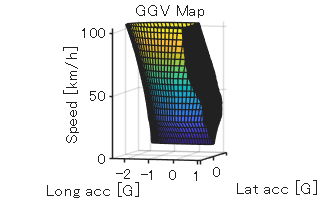

% ggv map
surf(GGV(:,:,2),GGV(:,:,1),GGV(:,:,3))
grid on
title('GGV Map')
xlabel('Lat acc [G]')
ylabel('Long acc [G]')
zlabel('Speed [km/h]')
view(105,5)
set(gca,'DataAspectRatio',[1 1 20])

#### 結果を集約してcsvで出力する

% %結果をまとめる
% result = table(v,axmax_dec,axmax_acc,aymax,phimax, ...
%     'VariableNames',{'速度 [km/h]','減速G [G]','加速G [G]','横G [G]','ロール角 [rad]'});
% 
% timestamp = datestr(now, 'yyyymmdd_HHMMSS');
% 
% filename = ['result_' timestamp '.csv'];% ファイル名を作成
% 
% writetable(result, filename, 'Encoding', 'Shift_JIS');% 保存